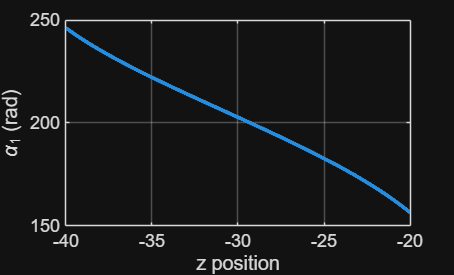

c = 12.75;  % Länge Oberarm
e = 9;      % Abstand Oberarm Mitte
d = 30;     % Länge Unterarm
f = 4.25;   % Abstand Unterarm Mitte

m = e - f;

i_vals = -20:-0.01:-40;
alpha_vals = zeros(size(i_vals));

for k = 1:length(i_vals)
    i = i_vals(k);

    D = [0 0 i];
    xD = D(1);
    yD = D(2);
    zD = D(3);
    
    u = xD^2 + yD^2 + zD^2 + m^2 + c^2 - d^2 + 2*yD*m;
    
    a = yD + m;
    b = u / (2 * c);
    
    alpha = 2*atan((zD - sqrt(zD^2 + a^2 - b^2)) / (a + b));
    alpha_vals(k, 1) = alpha;


    D12 = [(-0.5*xD + sqrt(3)/2 * yD) (-sqrt(3)/2 * xD - 0.5*yD) (zD)];
    xD2 = D12(1);
    yD2 = D12(2);
    zD2 = D12(3);
    
    u = xD2^2 + yD2^2 + zD2^2 + m^2 + c^2 - d^2 + 2*yD2*m;
    
    a = yD2 + m;
    b = u / (2 * c);
    
    alpha = 2*atan((zD2-sqrt(zD2^2 + a^2 - b^2)) / (a + b));
    alpha_vals(k, 2) = alpha;

    D13 = [(-0.5*xD - sqrt(3)/2 * yD) (sqrt(3)/2 * xD - 0.5*yD) (zD)];
    xD3 = D13(1);
    yD3 = D13(2);
    zD3 = D13(3);
    
    u = xD3^2 + yD3^2 + zD3^2 + m^2 + c^2 - d^2 + 2*yD3*m;
    
    a = yD3 + m;
    b = u / (2 * c);
    
    alpha = 2*atan((zD3-sqrt(zD3^2 + a^2 - b^2)) / (a + b));
    alpha_vals(k, 3) = alpha;
end


figure
alpha_vals_deg = rad2deg(alpha_vals);

max_deg = max(alpha_vals_deg(:,1));

rows = alpha_vals_deg(:,1) < 0;
alpha_vals_deg(rows,1) = alpha_vals_deg(rows,1) + 2*max_deg;
rows = alpha_vals_deg(:,2) < 0;
alpha_vals_deg(rows,2) = alpha_vals_deg(rows,2) + 2*max_deg;
rows = alpha_vals_deg(:,3) < 0;
alpha_vals_deg(rows,3) = alpha_vals_deg(rows,3) + 2*max_deg;

plot(i_vals, alpha_vals_deg(:,1),'LineWidth',2)
xlabel('z position')
ylabel('\alpha_1 (rad)')
grid on

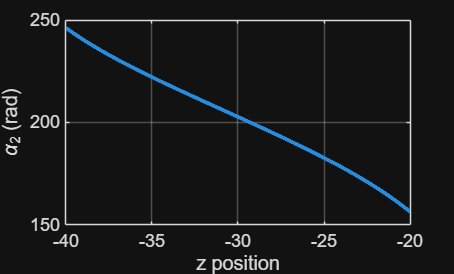

plot(i_vals, alpha_vals_deg(:,2),'LineWidth',2)
xlabel('z position')
ylabel('\alpha_2 (rad)')
grid on

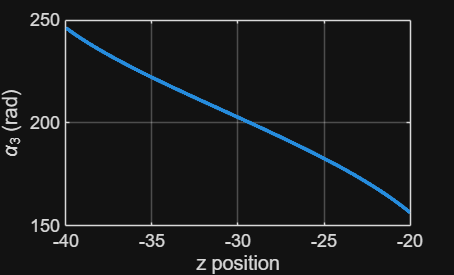

plot(i_vals, alpha_vals_deg(:,3),'LineWidth',2)
xlabel('z position')
ylabel('\alpha_3 (rad)')
grid on

D12 = [(-0.5*xD + sqrt(3)/2 * yD) (-sqrt(3)/2 * xD - 0.5*yD) (zD)]

D12 =      0     0   -40


xD = D12(1);
yD = D12(2);
zD = D12(3);

u = xD^2 + yD^2 + zD^2 + m^2 + c^2 - d^2 + 2*yD*m;

a = yD + m;
b = u / (2 * c);

alpha2 = 2*atan((zD-sqrt(zD^2 + a^2 - b^2)) / (a + b))

alpha2 = -1.9848

alpha2 = mod(rad2deg(alpha2) + 236, 360)

alpha2 = 122.2819

D13 = [(-0.5*xD - sqrt(3)/2 * yD) (sqrt(3)/2 * xD - 0.5*yD) (zD)]

D13 =      0     0   -40


xD = D13(1);
yD = D13(2);
zD = D13(3);

u = xD^2 + yD^2 + zD^2 + m^2 + c^2 - d^2 + 2*yD*m;

a = yD + m;
b = u / (2 * c);

alpha3 = 2*atan((zD-sqrt(zD^2 + a^2 - b^2)) / (a + b))

alpha3 = -1.9848

alpha3 = mod(rad2deg(alpha3) + 236, 360)

alpha3 = 122.2819